# Fitting 2nd Order Poles

We want to be able to idenitfy an unknown system from its time response.  To demonstrate this here is some data from the step response of some system.  For this system we know that the input is a 5-volt step.

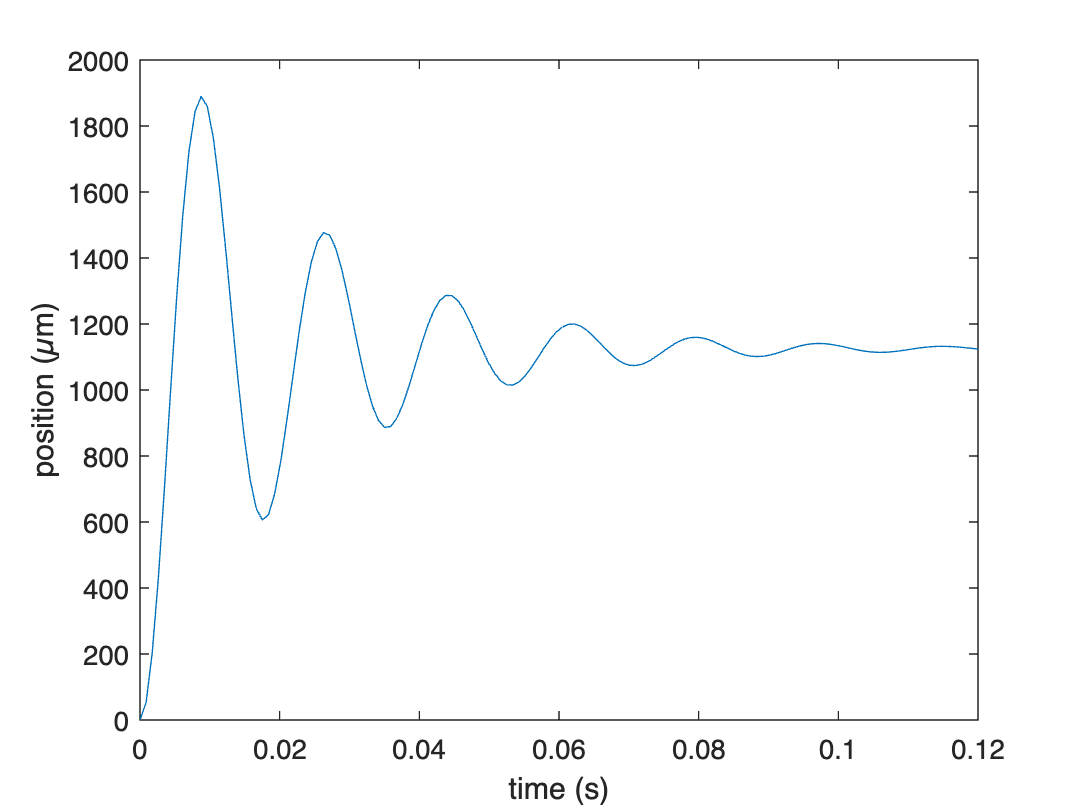

load data2.mat
plot(t,y)
xlabel('time (s)')
ylabel('position (µm)')

The response clearly has oscillations, so we should assume second-order poles.  We will assume the system has the form


$$G(s) = A \frac{\omega_n^2}{s^2 + 2\zeta\omega_ns + \omega_n^2$$


Our task is to identify the three parameters

- Gain $A$

- Natural frequency $\omega_n$

- Damping ratio $\zeta$

The gain $A$ is straightforward using the final value theorem.  We know the input is a 5-volt step.


$$\hat{u}(s) = \frac{5}{s}$$


so the Laplace transform of the output is


$$\hat{y}(s) = G(s) = A \frac{\omega_n^2}{(s^2 + 2\zeta\omega_ns + \omega_n^2)} \frac{5}{s}$$



$$y_{ss} = \lim_{t \rightarrow \infty} y(t) = \lim_{s \rightarrow 0} s\hat{y}(s) = \lim_{s \rightarrow 0} \frac{A \omega_n^2 5}{s^2 + 2\zeta\omega_ns + \omega_n^2} = 5A$$


We can find the final value with a datatip.

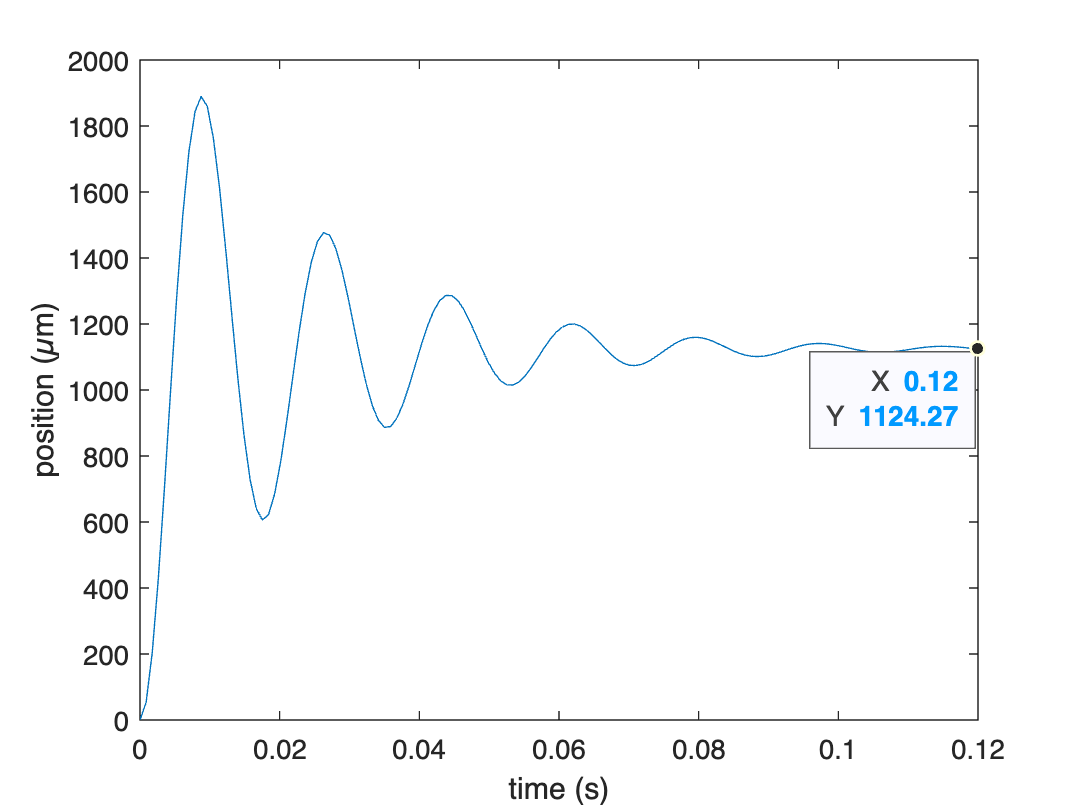

plot(t,y)
xlabel('time (s)')
ylabel('position (µm)')

ax = gca;
ax = gca;
chart = ax.Children(1);
datatip(chart,0.12,1100,'location','southwest');

A = 1124/5

A = 224.8000

Now we can use log-decrement to find the damping ratio.


$$\delta = \ln \frac{ x(t_1) }{ x(t_2) }$$



$$\zeta = \sqrt{ \frac{ \delta^2 }{ (2\pi)^2 + \delta^2 }$$


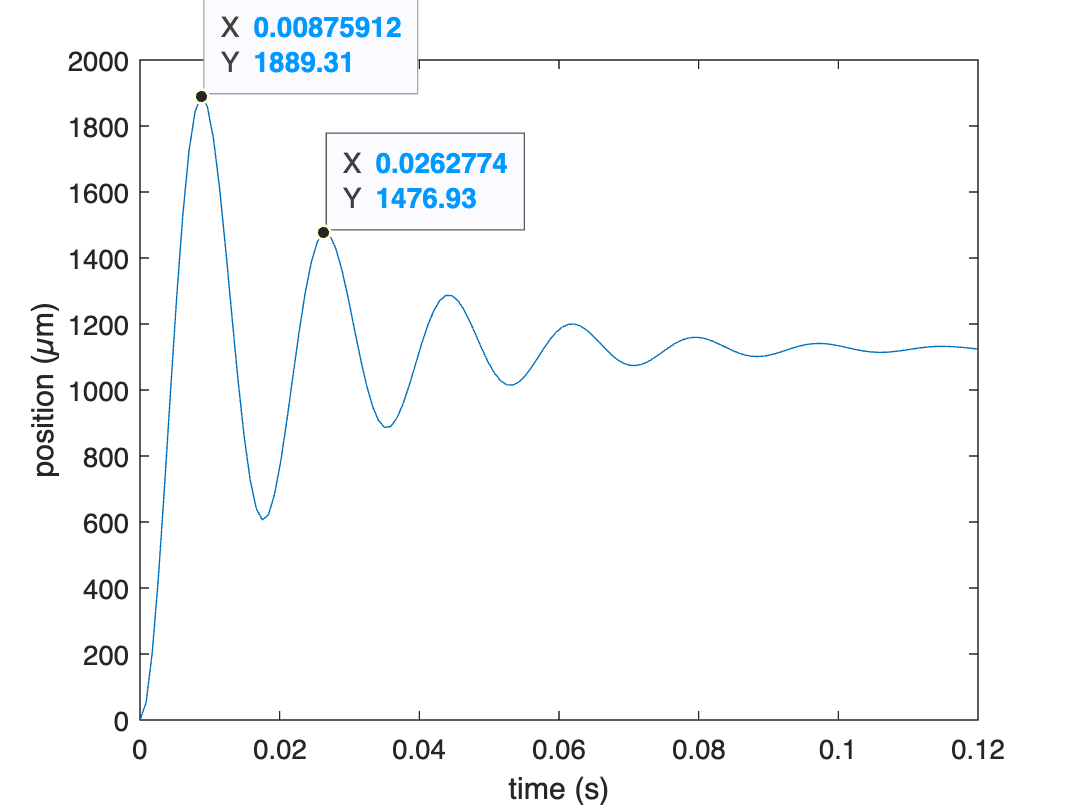

plot(t,y)
xlabel('time (s)')
ylabel('position (µm)')

ax = gca;
chart = ax.Children(1);
datatip(chart,0.0088,1900,'Location','northeast');
datatip(chart,0.0265,1470,'Location','northeast');

x1 = 1889 - 1124;
x2 = 1477 - 1124;
delta = log(x1/x2)

delta = 0.7734

zeta = sqrt(delta^2/((2*pi)^2 + delta^2))

zeta = 0.1222

We should note that $\delta < 2$ which means we are probably lightly damped, so we can use the approximation

$\zeta \simeq \frac{\delta}{2 \pi}$ if $\delta < 2$

zeta = delta/2/pi

zeta = 0.1231

Which is a reasonable approximation to the 'exact' answer above.

The damped period is the difference between the times $t_1$ and $t_2$.


$$T_d = t_2 - t_1$$


Td = 0.02628 - 0.008759

Td = 0.0175

With this we can directly calculate the damped natural frequency and the natural frequency.


$$\omega_d = \frac{2 \pi}{T_d}$$



$$\omega_n = \frac{ \omega_d}{\sqrt{ 1 - \zeta^2}}$$


omega_d = 2*pi/Td

omega_d = 358.6088

omega_n = omega_d/sqrt(1-zeta^2)    % rad/s

omega_n = 361.3568

f_n = omega_n/(2*pi)                % Hz

f_n = 57.5117

## Summary

The transfer function for the system is 


$$G(s) = A \frac{\omega_n^2}{s^2 + 2\zeta\omega_ns + \omega_n^2$$


and the parameters are

- 
$$A = 225 \; \text{µm/V}$$


- 
$$\zeta = 0.12$$


- 
$$\omega_n = 360 \; \text{rad/s} = 58 \; \text{Hz}
$$


We can build the model and compare its step response with the data.

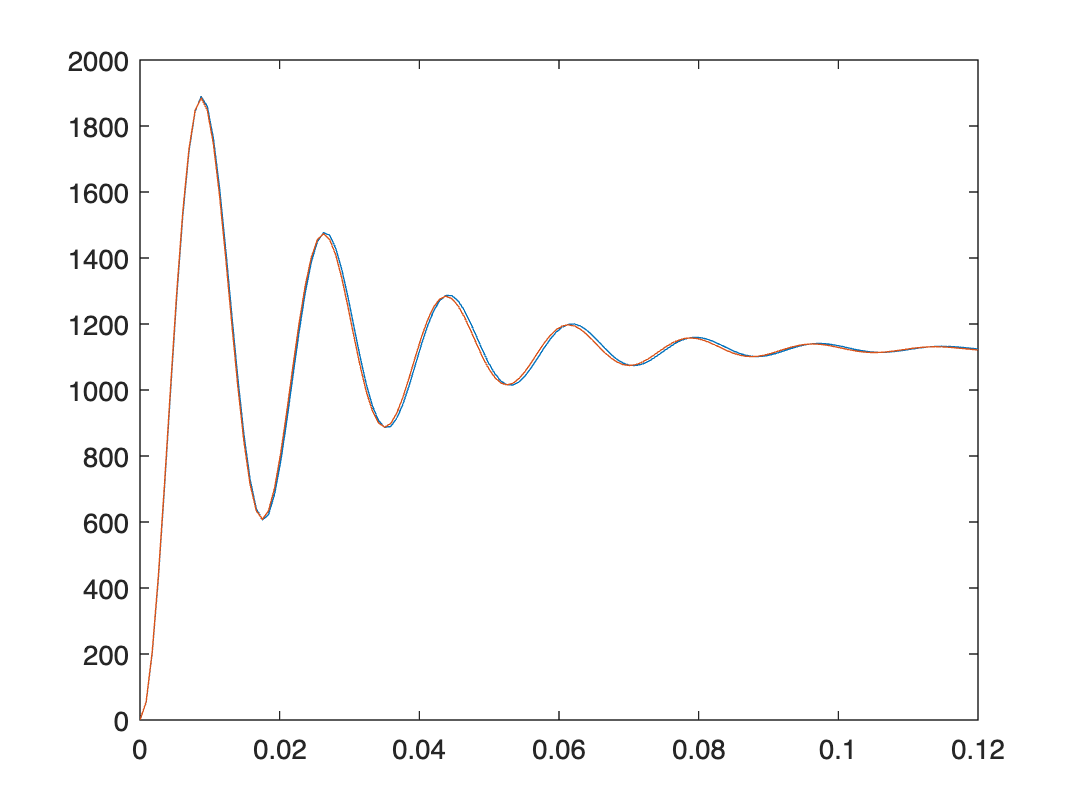

G = tf(A*omega_n^2,[ 1 2*zeta*omega_n omega_n^2 ]);
ymodel = step(G*5,t);

plot(t,y,t,ymodel)

Pretty good job!